maxEpochs = 50;
slice = 5000;
rng default

ds = load('LabledData\raw_labled.mat', 'ls');
ds = ds.ls.Labels;
lables = ds.detect_blinks;
dir = ds.Properties.RowNames;


Ds = {};
for i = 1:numel(dir)    
    raw_data = csvread(dir{i},1,1);
    filtered_data = hl_filter(raw_data(:,1));
    lable = lables(i);
    masked = getmask({filtered_data,lable{1,1}});
    Ds{i} = masked;  
end

chopedDs = {};
for i = 1:numel(Ds)
    for j = 1:(slice-1):numel(Ds{i}{1})-(slice-1)
        chopedDs{end+1} = {Ds{i}{1}(j:j+slice-1).',Ds{i}{2}(j:j+slice-1).'};        
    end
end

XTrain = {};
YTrain = {};

for i = 1:numel(chopedDs)
    XTrain{end+1} = chopedDs{i}{1};
    YTrain{end+1} = chopedDs{i}{2};
end
XTrain;
YTrain;
[trainIdx,~,testIdx] = dividerand(numel(XTrain),0.7,0,0.3);

XTest = XTrain(testIdx);
YTest = YTrain(testIdx);
XTrain = XTrain(trainIdx);
YTrain = YTrain(trainIdx);

trainDs = {XTrain, YTrain};
testDs = {XTest, YTest};

tallTrainSet = tall(trainDs);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).


tallTestSet = tall(testDs);
trainData = gather(tallTrainSet);
testData = gather(tallTestSet);

% for i = 1:numel(XTrain)
%     mu = mean([XTrain{i}],2);
%     sig = std([XTrain{i}],0,2);
%     XTrain{i} = (XTrain{i} - mu) ./ sig;
% end

% results = bayesopt(objectFunction,optimVars,'UseParallel',true);

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998



     1



     1

    0.9998



     1

    0.9998



     1

    0.9998

    0.9998

    0.9998

    0.9998



     1

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998



     1

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998

    0.9998



     1

    0.9998

    0.9998

    0.9998



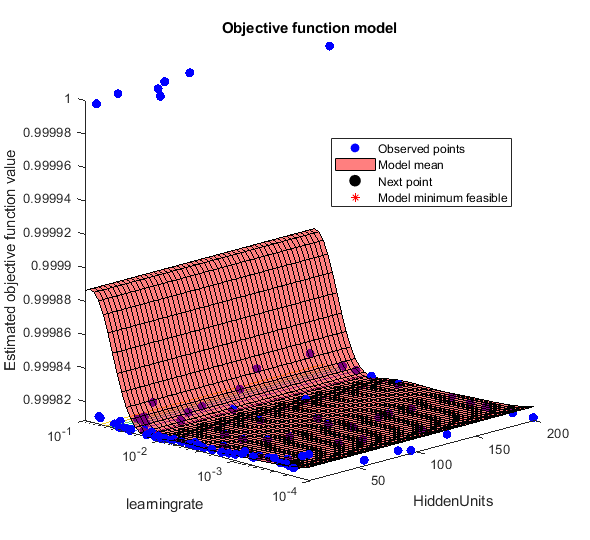

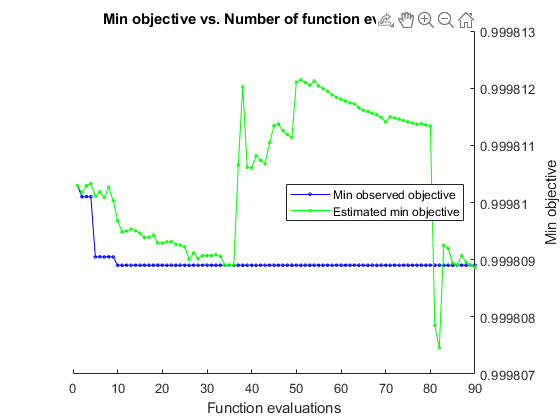


optimVars = [
    optimizableVariable('HiddenUnits',[8 200],'Type','integer')

    % optimizableVariable('MiniBatchSize',{'8' '16'},'Type','categorical')
%     optimizableVariable('DropOutRate', {'0.3' '0.5' '0.7' },'Type','categorical')
    optimizableVariable('learningrate',[1e-4 1e-1],'Type','real',"Transform","log")];

    objectFunction = objectFunctionLF_0(trainDs, testDs,  maxEpochs);
    
    % optimizer
    BayesObject = bayesopt(objectFunction, optimVars, ...
        'MaxTime',10*60*60, ...
        'Verbose',0,...
        "UseParallel",false,...
        'IsObjectiveDeterministic',false, ...
        'ParallelMethod',"clipped-model-prediction",...
        'MaxObjectiveEvaluations',90,...
        'ExplorationRatio',0.6,...
        'AcquisitionFunctionName', 'expected-improvement-per-second-plus');


    % Evaluate and train the network with the optimal parameters
    [valError,~,net, Ys, YPred, YPredStep, YTest] = BayesObject.ObjectiveFcn(optimVars,1);

Unrecognized method, property, or field 'HiddenUnits' for class 'optimizableVariable'.

Error in objectFunctionLF_0/valErrorFun (line 11)
        numHiddenUnits = optVars.HiddenUnits;

    % get the best point of the Bayesian Optimizaion
    optVars = bestPoint(BayesObject);
    % evaluate the net performance
%     sMAPErr = sMAPE(con2seq(YTest) ,con2seq(YPred));
save("8604\hyperParameter\LSTM_0.mat","optVars","-mat")